## SADDLE 

Simulated Annealing using Dimer Likelihood Estimation [1]

Load primer candidates as computed by PriSeT [4] on X. Note: reverse primers are notated in same direction as fwd, but SADDLE needs them reverse complementary. We will store all primers flat in a (const) array of length 2n. As redundant sequences are removed, there might be a significant disbalance between forward and reverse primers.

Next Tasks:

- Setup GitHub, done

- display proportion fwd/rev primers in final set

- better normalization, email authors directly

- compare to raw gradient descent, done

- usage with metabarcoding primers

- Check paper how many primers to swap per iteration, more than one?

% Note: reverse primers are notated in same direction as fwd, but SADDLE needs
% them reverse complementary

primer_file = "primers/covid.csv"

primer_file = "primers/covid.csv"

num_primers = 24

num_primers = 24

dimer_range = [4:8]

dimer_range =      4     5     6     7     8


g_T = 150 % total number iters anneal + SGD

g_T = 150

g_t = 100 % total number iters anneal < g_T

g_t = 100

num_swapped = 1

num_swapped = 1

opts = detectImportOptions(primer_file);
opts.SelectedVariableNames = ["primer_fwd", "primer_rev"];
T = table2array(readtable(primer_file, opts));
S_fwd = unique(T(:,1));
S_rev = unique(T(:,2));
% keep direction information, f forward, r reverse, b both
Dir = containers.Map(S_fwd, repmat({'f'}, numel(S_fwd), 1));
for i = 1:numel(S_rev)
    s_rev = S_rev{i};
    if isKey(Dir, s_rev)
        sprintf('Found identical fwd and rev primer: %s', s_rev)
        Dir(s_rev) = 'b';
    else
        Dir(s_rev) = 'r';
    end
end

ans = 'Found identical fwd and rev primer: TGTGGGCTCAATGTGTCC'

S = [S_fwd; S_rev];

### PCR Settings

% nucleic acid concentration [pM]
C = 250

C = 250

% R     molar gas constant [cal/°C * mol]
R = 1.987

R = 1.9870

% default temperature set to room temperature 25˚C = 298.15 K
DG_temp = 293.15

DG_temp = 293.1500

% salt concentration [mM]
Mg =  1.5

Mg = 1.5000

% mvi   monovalent ion concentration
mvi = 1.5

mvi = 1.5000


argv = containers.Map({'C', 'DG_temp', 'R', 'Mg', 'mvi'}, {C, DG_temp, R, Mg, 50});

Read enthalpy and entropy tables as provided in http://www.premierbiosoft.com/netprimer/netprlaunch/Help/Appendix_A_Tables.htm#Bookmark_AppendixA_2.

dH_table = readtable("enthalpy.csv")

dH_table = 4×4 table
    Var1    Var2     Var3     Var4
    ____    _____    _____    ____

    9100     6500     7800    8600
    5800    11000    11900    7800
    5600    11100    11000    6500
    6000     5600     5800    9100


dS_table = readtable("entropy.csv")

dS_table = 4×4 table
    Var1    Var2    Var3    Var4
    ____    ____    ____    ____

      24    17.3    20.8    23.9
    12.9    26.6    27.8    20.8
    13.5    26.7    26.6    17.3
    16.9    13.5    12.9      24


Filter primer sequences for free energy in [-12.5:-10.5] dGº

n = length(S);
disp(['Number of input primer sequences: ', int2str(n)])

Number of input primer sequences: 90


S_dG = arrayfun(@(s)(freeEnergy(s, dH_table, dS_table, argv)), S)

S_dG =   -34.0049
  -34.2723
  -34.6822
  -32.8216
  -34.4373
  -32.8438
  -32.2657
  -30.7424
  -33.4983
  -32.8000


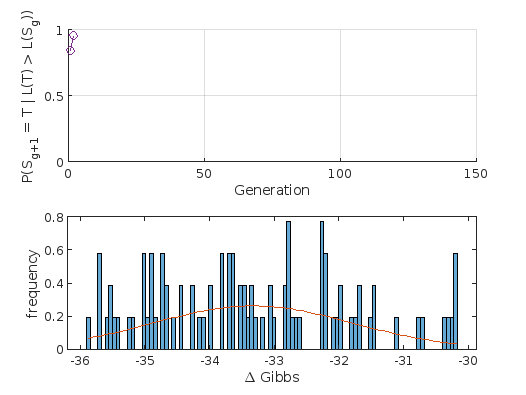

histogram(S_dG, 100, 'Normalization', 'pdf'), hold on,
smean = mean(S_dG);  % sample mean
sdev = sqrt(var(S_dG));  % sample variance
x = min(S_dG):(max(S_dG) - min(S_dG))/100: max(S_dG);
plot(x, normpdf(x, smean, sdev))
hold off
xlabel('\Delta Gibbs')
ylabel('frequency')

n = numel(S)

n = 90


% Filter for dG above 5 and below 95 percentile. Unit: [kcal/mol]
% human DNA: [-12.5 : -10.5], RNA: ? 
if n >= 100
    alpha = .10;
    qs = quantile(S_dG, [alpha/2 1-alpha/2]);
    dG_min = qs(1)
    dG_max = qs(end)
    S = S(S_dG(:,1) >= qs(1) & S_dG(:,1) <= qs(end));
    sprintf('Removed %i sequences s.t. dG in [%d:%d]', ...
        n-numel(S), qs(1), qs(end))
    n = numel(S)
end


Pre-compute badness of identity, i.e., B_id(i) = badness(p_i, p_i):

B_id = zeros(numel(S), 1);
for i = 1:numel(S)
    B_id(i) = badness(S, dimer_range, i, i);
end

### Initialization

Start with random subset of size num_primers and compute initial loss:

rng(0); % seed generator
I = randperm(length(S));
mask = boolean(zeros(n, 1));
mask(I(1:num_primers)) = 1;

#### Global hash H for accelerated loss computation

For current set S(mask) it accumulates 1/(d + 1)

H = init_hash(S, mask, dimer_range);

### SADDLE Algorithm

Generate a temporary primer set T based on set S_g (primer set from previous generation g) by randomly changing 1 or more primers.

Evaluate Loss L(T), and set S_{g+1} to either S_g (no change) or T, depending probabilistically on the relative values of L(S_g) and L(T).

Repeat steps 3 to 4 until an acceptable primer set S_final is constructed

% compute sample variance of loss for normalization
losses = zeros(10,1);
for i = 1:10
    I_aux = randperm(length(S));    
    mask_aux = boolean(zeros(n, 1));
    mask_aux(I_aux(1:num_primers)) = 1;
    losses(i) = Loss(S, mask_aux, dimer_range, H, B_id);
end
% losses
dev_loss = sqrt(var(losses))

dev_loss = 403.5075

loss = Loss(S, mask, dimer_range, H, B_id);
g = 1; % iteration counter
loss_vec = zeros(g_t, 1);
eps = .03 % decrease factor for probability normalization

eps = 0.0300

C_g = Loss(S, ones(numel(S),1), dimer_range, H, B_id);
C_g = 2 * C_g * num_primers / numel(S);

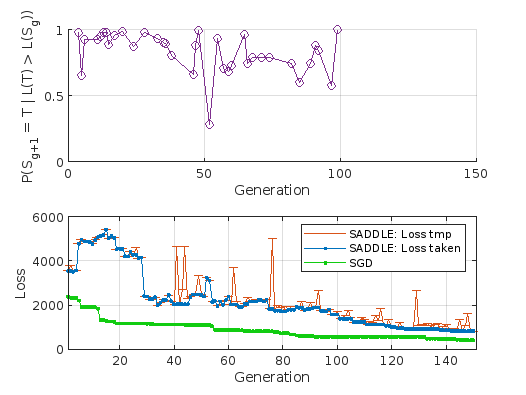

% clear all; clc; close all;
lilac = '#7E2F8E'; blue = '#0072BD'; orange = '#D95319'; green = '#11CC11';

sub1 = subplot(2,1,1);
cla(sub1);
axis(sub1, [0, g_T, 0, 1]);
an0 = animatedline(sub1, 'Color', lilac, 'Marker', 'o', 'Clipping', 'off', 'DisplayName', 'Prob when $L(T) > L(S_g)$');
grid(sub1, 'on');
ylabel('P(S_{g+1} = T | L(T) > L(S_g))');
xlabel('Generation');

sub2 = subplot(2,1,2);
cla(sub2);
an1 = animatedline(sub2, 'Color', orange, 'Marker', '_', 'DisplayName', 'SADDLE: Loss tmp', 'Clipping', 'off');
an2 = animatedline(sub2, 'Color', blue, 'Marker', '.', 'DisplayName', 'SADDLE: Loss taken', 'Clipping', 'off');
an3 = animatedline(sub2, 'Color', green, 'Marker', '.', 'DisplayName', 'SGD', 'Clipping', 'off');

addpoints(an1, 1, loss);
grid(sub2, 'on');
xlabel('Generation');
ylabel('Loss');
xlim([1 g_T+1]);
legend
mask_sgd = mask;
H_sgd = containers.Map(H.keys, H.values);
loss_sgd = loss;
while g <= g_T
    % annealing + SGD
    i_del = get_rand_index(mask, 1); % random index 1 -> 0
    i_ins = get_rand_index(mask, 0); % random index 0 -> 1 
    
    mask_tmp = mask;
    
    if mask(i_del) == 0
        error('i_del already deleted')
    end
    if mask(i_ins) == 1
        error('i_ins already set')
    end
    mask_tmp([i_del i_ins]) = [0 1];  % swap indices
    if sum(mask) ~= sum(mask_tmp)
        error('check bit setting in tmp mask')
    end
    H_tmp = containers.Map(H.keys, H.values); 
    H_tmp = update_hash(H_tmp, S, dimer_range, i_del, i_ins);
    loss_tmp = Loss(S, mask_tmp, dimer_range, H_tmp, B_id);
    p = exp((loss - loss_tmp) / C_g);
    if loss_tmp < loss
        mask = mask_tmp;
        H = H_tmp;
        loss = loss_tmp;
    else
        if g <= g_t && rand() <= p
            addpoints(an0, g, p);
            mask = mask_tmp;
            H = H_tmp;
            loss = loss_tmp;
        end
    end

    addpoints(an1, g, loss_tmp);
    addpoints(an2, g, loss);

    % annealing only as baseline comparison
    i_sgd_del = get_rand_index(mask_sgd, 1); % random index 1 -> 0
    i_sgd_ins = get_rand_index(mask_sgd, 0); % random index 0 -> 1 
    mask_sgd_tmp = mask_sgd;
    mask_sgd_tmp([i_sgd_del i_sgd_ins]) = [0 1];  % swap indices
   
    H_sgd_tmp = containers.Map(H_sgd.keys, H_sgd.values); 
    H_sgd_tmp = update_hash(H_sgd_tmp, S, dimer_range, i_sgd_del, i_sgd_ins);
    loss_sgd_tmp = Loss(S, mask_sgd_tmp, dimer_range, H_sgd_tmp, B_id);

    if loss_sgd_tmp < loss_sgd
        H_sgd = H_sgd_tmp;
        mask_sgd = mask_sgd_tmp;
        loss_sgd = loss_sgd_tmp;
    end
    addpoints(an3, g, loss_sgd);    

    drawnow

    g = g + 1;
    C_g = C_g * (1 - eps);
end

[1] Xie, N.G., Wang, M.X., Song, P. *et al.* "Designing highly multiplex PCR primer sets with Simulated Annealing Design using Dimer Likelihood Estimation (SADDLE)", *Nat Commun* **13, **1881 (2022). https://doi.org/10.1038/s41467-022-29500-4

[2] Breslauer, K.J., Frank, R., Blocker, H., and Markey, L. A. (1986)  "Predicting DNA duplex stability from the base sequence",  Proc. Natl. Acad. Sci. USA 83, 3746-3750.

[3] Handbook of Biochemistry and Molecular Biology (1975) Fasman G.D.,  ed., 3rd edition, Nucleic Acids - Vol. 1, 589, CRC Press, Cleveland, OH.

[4]  Hoffmann, M., Monaghan, M.T., Reiner, K. (2021). "PriSeT: efficient de novo primer discovery", In Proceedings of the 12th ACM Conference on Bioinformatics, Computational Biology, and Health Informatics (BCB '21). Association for Computing Machinery, New York, NY, USA, Article 2, 1–12. https://doi.org/10.1145/3459930.3469546